clear; clc;
close all;

%% Text Size
set(0,'DefaultAxesFontsize',8);
set(0,'DefaultTextFontsize',8);

%% Text Fonts
set(0,'DefaultTextFontname','Arial');
set(0,'DefaultAxesFontname','Arial');


filename = "fig2_succ_reservoir";
load("data\" + filename + ".mat");

disp(filename);

fig2_succ_reservoir


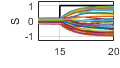

figsize = [10,10,2,1.8];
figpos = [0.32 0.39 0.63 0.6];

figure('Color',[1 1 1]);
set(gcf,'unit','centimeters','position',figsize);
set(gca,'Position', figpos);
set(gcf,'Visible','on');

p1 = plot(tstep, inputstep, 'k');
p1.LineWidth = 1.2;
grid on;
hold on;
p2 = plot(tstep, internalstatesstep(:,:));
ylabel('S');
xlim([13 20]);
ylim([-1.3 1.3]);

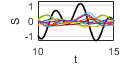

figure('Color',[1 1 1]);
set(gcf,'unit','centimeters','position',figsize);
set(gca,'Position', figpos);
set(gcf,'Visible','on');

p1 = plot(tsin(1:2001), inputsin(1:2001), 'k');
p1.LineWidth = 1.2;
grid on;
hold on;
p2 = plot(tsin(1:2001), internalstatessin(1:2001,21:30));
xlabel('t', 'Position', [12.5 -2]);
ylabel('S');
xlim([10 15]);
ylim([-1.3 1.3]);

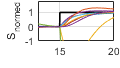

figure('Color',[1 1 1]);
set(gcf,'unit','centimeters','position',figsize);
set(gca,'Position', figpos);
set(gcf,'Visible','on');

p1 = plot(tstep,inputstep, 'k');
p1.LineWidth = 1.2;
hold on;
grid on;
p2 = plot(tstep,normstep(:,21:30));
% xlabel('t');
xlim([13 20]);
% xticks([0.4 0.5]);
ylim([-1 1.8]);
ylabel('S_{normed}');

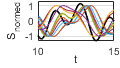


figure('Color',[1 1 1]);
set(gcf,'unit','centimeters','position',figsize);
set(gca,'Position', figpos);
set(gcf,'Visible','on');

p1 = plot(tsin(1:2001),inputsin(1:2001), 'k');
p1.LineWidth = 1.2;
hold on;
grid on;
p2 = plot(tsin(1:2001),normsin(1:2001,21:30));
% for i = 1:10
%     p2(i).Color = colors(i,:);
% end
% xlabel('t');
xlim([10 15]);
ylim([-1.3 1.3]);
xlabel('t', 'Position', [12.5 -2]);
ylabel('S_{normed}');